## Look at a sample of the experiment table

experimentTable = bot.listExperiments("VisualBehavior")

experimentTable = 1936×32 table
       id        behavior_session_id    file_id    mouse_id    ophys_container_id    ophys_session_id          session_type           behavior_type     prior_exposures_to_session_type    targeted_structure    age_in_days    equipment_name    experience_level    image_set    imaging_depth    imaging_plane_group    indicator    passive    prior_exposures_to_image_set    prior_exposures_to_omissions          project_code          published_at    session_number    sex    targeted_imaging_depth                     full_genotype

### List all of the unique session types

uniqueSessionTypes = unique(experimentTable.session_type)

uniqueSessionTypes = 18×1 categorical array
     OPHYS_1_images_A 
     OPHYS_1_images_B 
     OPHYS_1_images_G 
     OPHYS_2_images_A_passive 
     OPHYS_2_images_B_passive 
     OPHYS_2_images_G_passive 
     OPHYS_3_images_A 
     OPHYS_3_images_B 
     OPHYS_3_images_G 
     OPHYS_4_images_A 
     OPHYS_4_images_B 
     OPHYS_4_images_H 
     OPHYS_5_images_A_passive 
     OPHYS_5_images_B_passive 
     OPHYS_5_images_H_passive 
     OPHYS_6_images_A 
     OPHYS_6_images_B 
     OPHYS_6_images_H 


### Select a "random" experiment

experimentId = 1085840400;
experiment = bot.getExperiments(experimentId)

experiment =   Experiment with properties:

                             id: 1085840400
                           info: [1×1 struct]
                    SessionType: OPHYS_1_images_A
                LinkedFilesInfo: dictionary (string ⟼ string) with 1 entry

   Linked Items
                      Container: [7×32 table]
                        Session: [1×29 table]
                          Cells: [153×4 table]

   Linked File Values ('OphysNWB')
            TwoPhotonParameters: [1x1 struct]              (download required)
              CellSpecimenTable: [?x13 table]              (download required)
           FovAverageProjection: [?x? uint8]               (download required)
           FovMaximumProjection: [?x? uint8]               (download required)
          SegmentationMaskImage: [?x? int64]               (download required)
      FluorescenceTracesDemixed: [?x1 timetable]           (download 

### Request a property value to trigger the download of the NWB data

experiment.Metadata

ans = struct with fields:
            institution: "Allen Institute for Brain Science"
                devices: [0×0 string]
            description: "2-photon calcium imaging in the visual cortex of the mouse brain as the mouse performs a visual change detection task with a set of natural images upon which it has been previously trained. Image stimuli are displayed for 250 ms with a 500 ms intervening gray period. 5% of non-change image presentations are randomly omitted. The session is 75 minutes long, with 5 minutes of gray screen before and after 60 minutes of behavior, followed by 10 repeats of a 30 second natural movie stimulus at the end of the session."
    session_description: "OPHYS_1_images_A"
     session_start_time: 22-Feb-2021 09:19:32
               keywords: ["2-photon"    "calcium imaging"    "visual cortex"    "behavior"    "task"]
     allen_project_code: 'VisualBehaviorMultiscope'
         equipment_name: 'MESO.1'
           session_type: 'OPHYS_1_images_A'


### Check out the experiment again

The experiment display is updated to show the size and availability of the NWB Data. Note that the Metadata is now in memory.

experiment

experiment =   Experiment with properties:

                             id: 1085840400
                           info: [1×1 struct]
                    SessionType: OPHYS_1_images_A
                LinkedFilesInfo: dictionary (string ⟼ string) with 1 entry

   Linked Items
                      Container: [7×32 table]
                        Session: [1×29 table]
                          Cells: [153×4 table]

   Linked File Values ('OphysNWB')
            TwoPhotonParameters: [1x1 struct]              (on-demand)
              CellSpecimenTable: [153x13 table]            (on-demand)
           FovAverageProjection: [512x512 uint8]           (on-demand)
           FovMaximumProjection: [512x512 uint8]           (on-demand)
          SegmentationMaskImage: [512x512 int64]           (on-demand)
      FluorescenceTracesDemixed: [48188x1 timetable]       (on-demand)
    FluorescenceTracesCorrected: [4818

### Look at the FOV Average Projection image

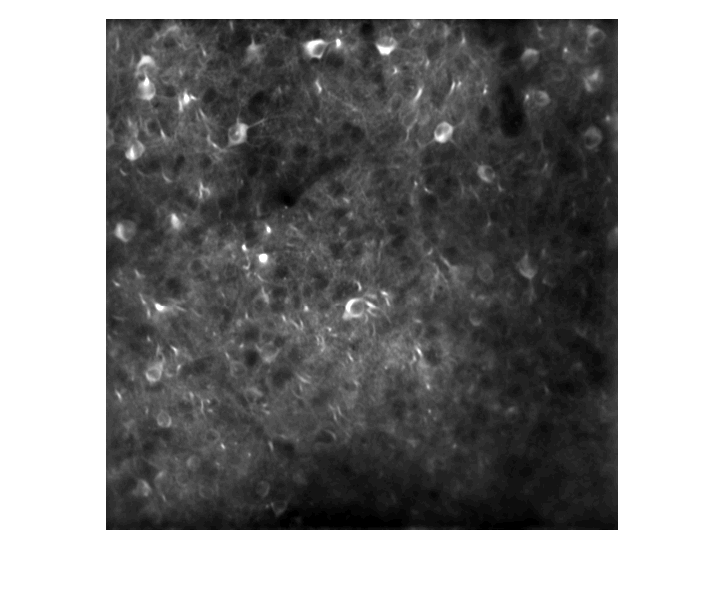

avgImage = experiment.FovAverageProjection;
avgImage = imadjust(avgImage, stretchlim(avgImage,[0.001, 0.999]));
f=figure; ax = axes(f); imshow(avgImage, 'Parent', ax)

### Check out the cell specimen table

experiment.CellSpecimenTable

ans = 153×13 table
    cell_specimen_id    cell_roi_id    height    mask_image_plane    max_correction_down    max_correction_left    max_correction_right    max_correction_up    valid_roi    width     x      y         roi_mask     
    ________________    ___________    ______    ________________    ___________________    ___________________    ____________________    _________________    _________    _____    ___    ___    _________________

       1120118128       1115339979       12             1                     6                     15        

If you scroll to the right most column you'll see that this table contains roi masks for each cell

### Plot the outlines of the rois on top of the average projection image

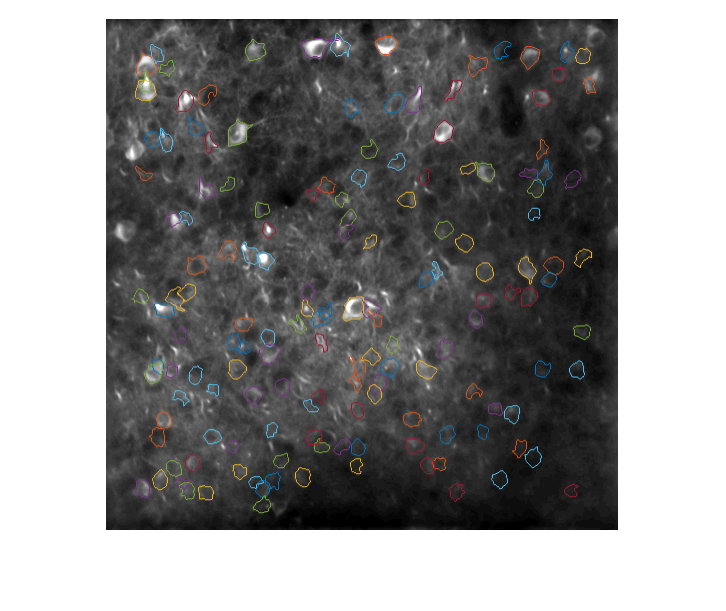

% Get and plot outlines of roi masks. 
f=figure(); ax = axes(f); imshow(avgImage, 'Parent', ax)
hold(ax, 'on')

roiMasks = experiment.CellSpecimenTable.roi_mask;
for i = 1:numel(roiMasks)
    B = bwboundaries(roiMasks{i});
    plot(ax, B{1}(:,2), B{1}(:,1)) % Note:  1st column is y-coordinates, 2nd column is x-coordinates
end

## Plot DFF traces

dff = experiment.FluorescenceTracesDFF

dff = 48188×1 timetable
    timestamps    FluorescenceTracesDFF
    __________    _____________________

    8.9543 sec        1×153 double     
    9.0478 sec        1×153 double     
    9.1413 sec        1×153 double     
    9.2348 sec        1×153 double     
    9.3283 sec        1×153 double     
    9.4218 sec        1×153 double     
    9.5153 sec        1×153 double     
    9.6088 sec        1×153 double     
    9.7023 sec        1×153 double     
    9.7958 sec        1×153 double     
    9.8893 sec        1×153 double     
    9.9828 sec        1×153 double     
    10.076 sec        1×153 double     
    10.17 sec         1×153 double     
    10.263 sec

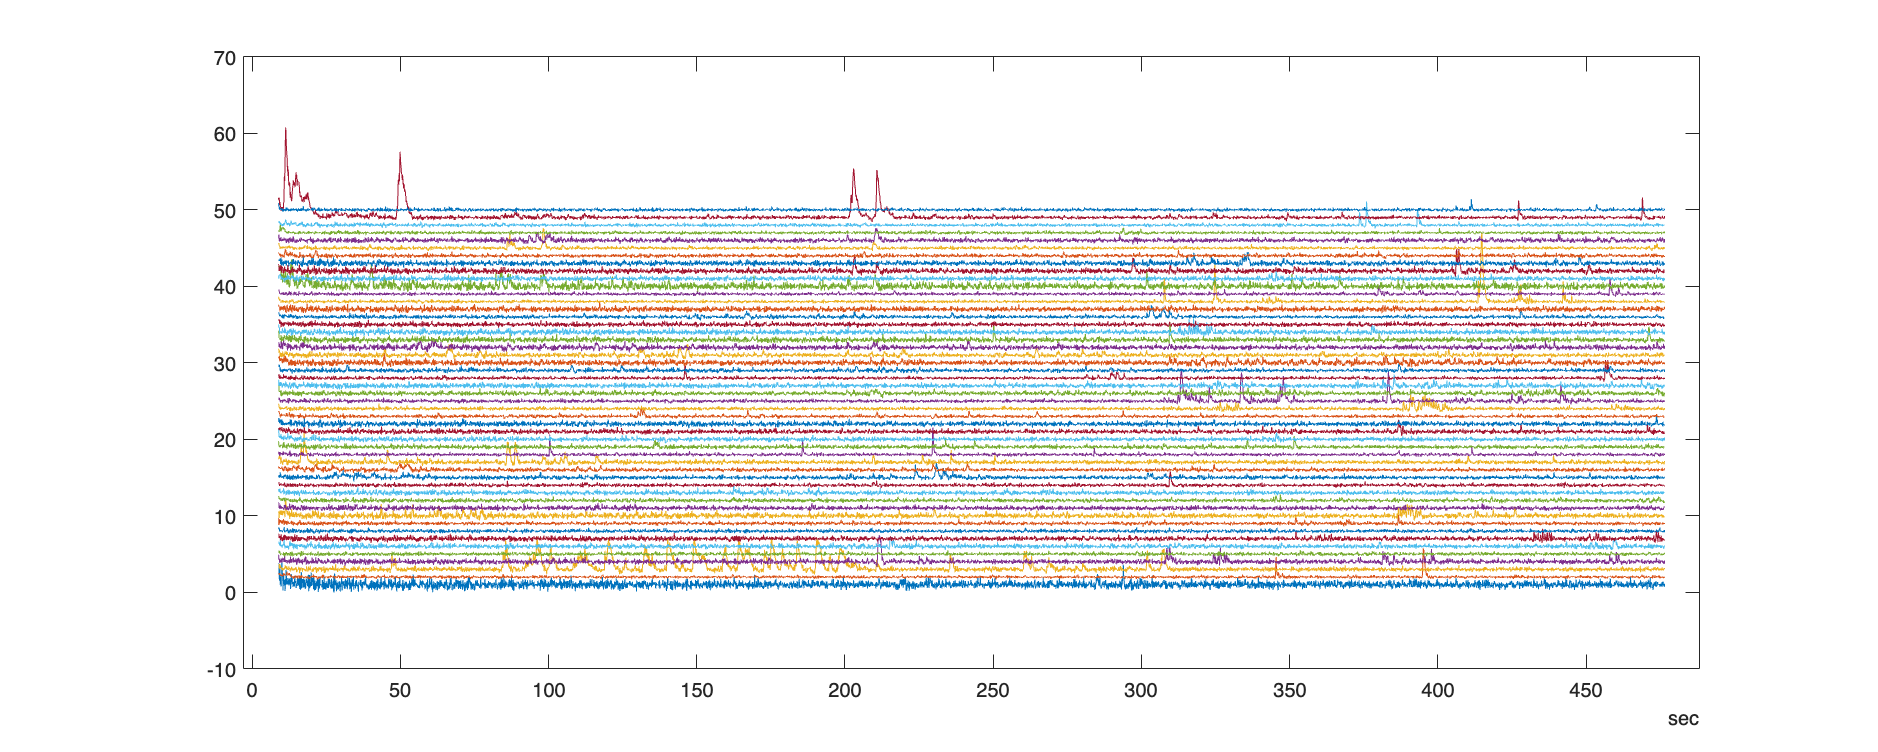

dffMatrix = dff.FluorescenceTracesDFF;
numCells = size(dffMatrix, 2);
dffMatrix = dffMatrix + (1:numCells);

f=figure('Position',[1,1,1000,400]); ax = axes(f); plot(dff.timestamps(1:5000), dffMatrix(1:5000, 1:50))

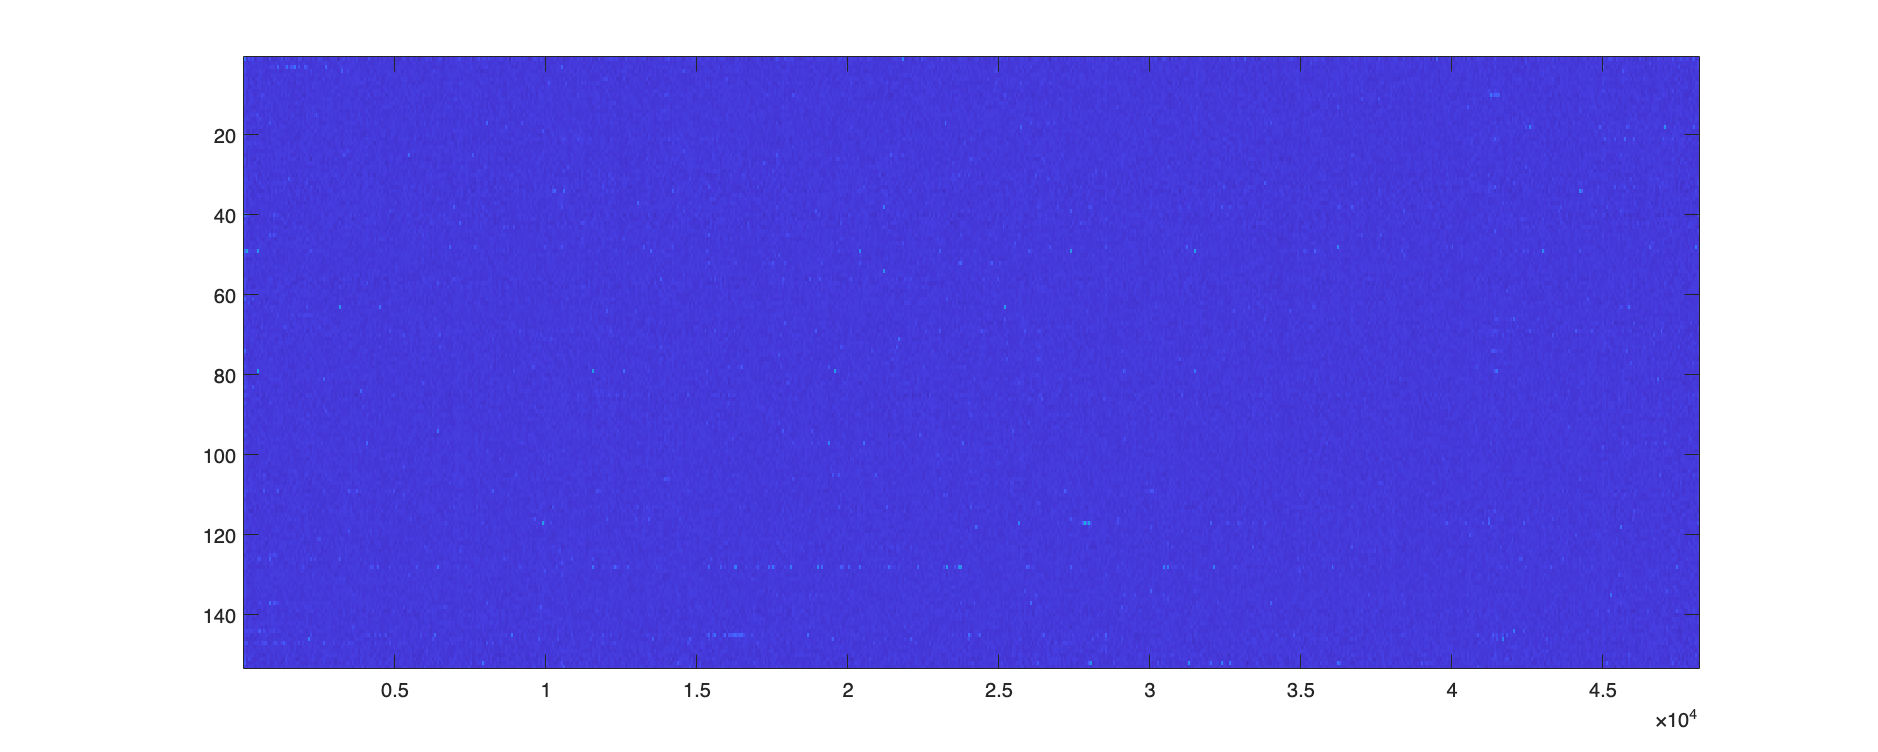

imagesc(dff.FluorescenceTracesDFF')

### Get some behavioral data

licks = experiment.Licks

licks = 945×1 timetable
    timestamps    frame
    __________    _____

    10.889 sec      115
    13.174 sec      252
    13.258 sec      257
    13.358 sec      263
    13.475 sec      270
    13.658 sec      281
    14.225 sec      315
    21.548 sec      754
    21.681 sec      762
    22.298 sec      799
    45.501 sec     2190
    45.634 sec     2198
    46.168 sec     2230
    113.77 sec     6283
    312.49 sec    18196
    312.74 sec    18211


rewards = experiment.Rewards

rewards = 38×2 timetable
    timestamps    volume    auto_rewarded
    __________    ______    _____________

    312.15 sec    0.005         true     
    324.15 sec    0.005         true     
    333.19 sec    0.005         true     
    340.68 sec    0.005         true     
    351.95 sec    0.005         true     
    432.75 sec    0.007         false    
    552.83 sec    0.007         false    
    560.96 sec    0.007         false    
    634.63 sec    0.007         false    
    654.97 sec    0.007         false    
    699.37 sec    0.007         false    
    762.35 sec    0.007         false    
    786.27 sec    0.007         false    
    803.67 se

running_speed = experiment.RunningSpeed

running_speed = 270179×1 timetable
    timestamps      speed  
    __________    _________

    8.9708 sec    -0.027868
    8.9875 sec     0.056828
    9.0042 sec      0.12195
    9.0209 sec      0.15405
    9.0376 sec      0.14863
    9.0543 sec      0.10992
    9.0709 sec     0.048156
    9.0876 sec    -0.023138
    9.1043 sec     -0.08923
    9.121 sec      -0.13711
    9.1376 sec     -0.15924
    9.1544 sec     -0.15583
    9.171 sec      -0.13396
    9.1877 sec      -0.1041
    9.2044 sec    -0.075441
    9.2211 sec    -0.052819


All the behavioral variables are available as timetables. That makes it easy to plot them on the same time base:

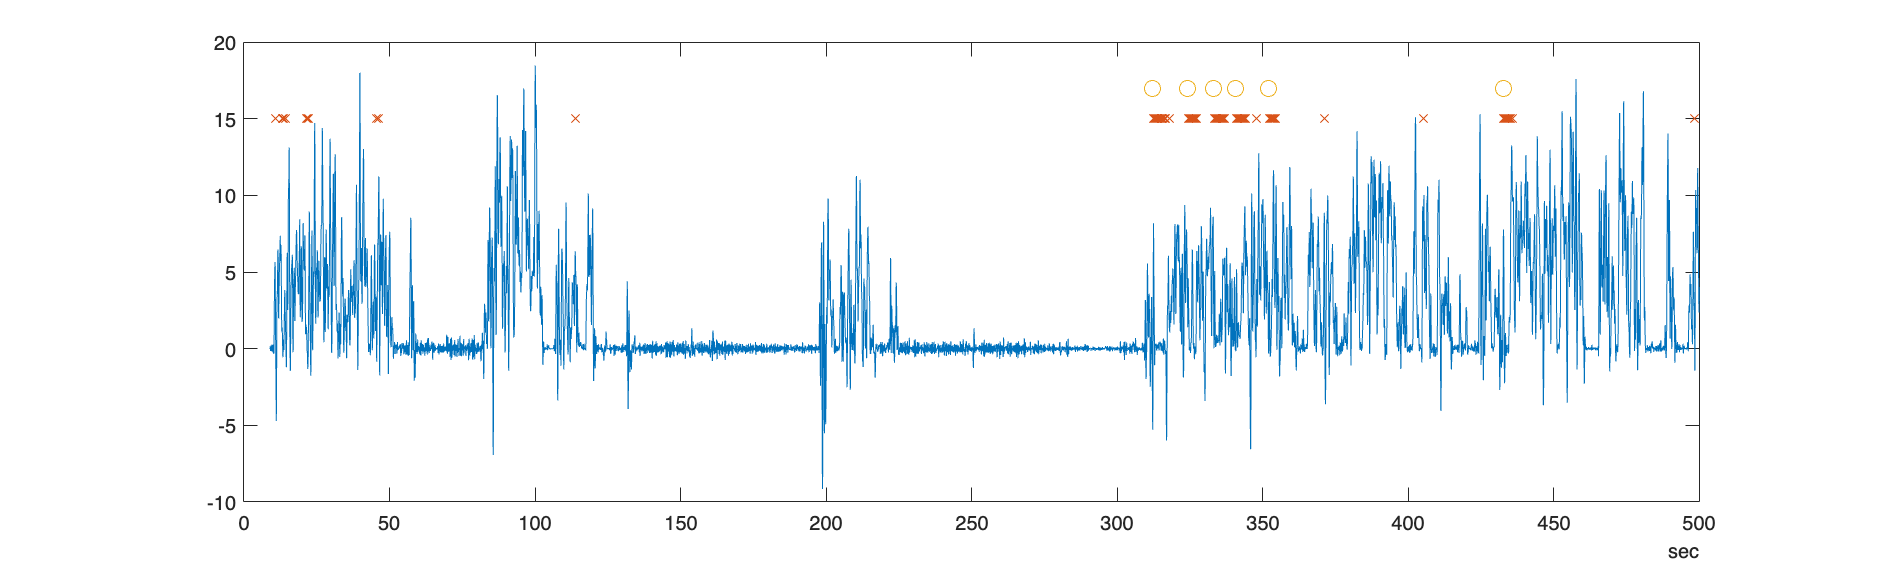

f=figure('Position',[1,1,1000,300]);
ax = axes(f);
plot(running_speed.timestamps, running_speed.speed)
hold(ax, 'on')
plot(licks.timestamps, 15*ones(size(licks.timestamps)), 'x')
plot(rewards.timestamps, 17*ones(size(rewards.timestamps)), 'o', 'MarkerSize', 8)
ax.XLim = seconds([0, 500]);
hold(ax, 'off')